%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'asm_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = '';

summaryTable = 1×11 table
    min     median    max    range     mean        std      interactionCount    synergyCount    antagonismCount    rejectNormality    pNormality
    ____    ______    ___    _____    _______    _______    ________________    ____________    _______________    _______________    __________

    -1.5     0.25     1.5      3      0.24493    0.50379          148                17               90                true            0.0005  


drugList = 18×1 cell array
    {'AMK'}
    {'AMP'}
    {'CHL'}
    {'CPR'}
    {'DOX'}
    {'ERY'}
    {'FOS'}
    {'FOX'}
    {'FUS'}
    {'GEN'}
    {'LOM'}
    {'NAL'}
    {'NIT'}
    {'SLF'}
    {'STR'}
    {'TET'}
    {'TOB'}
    {'TRM'}


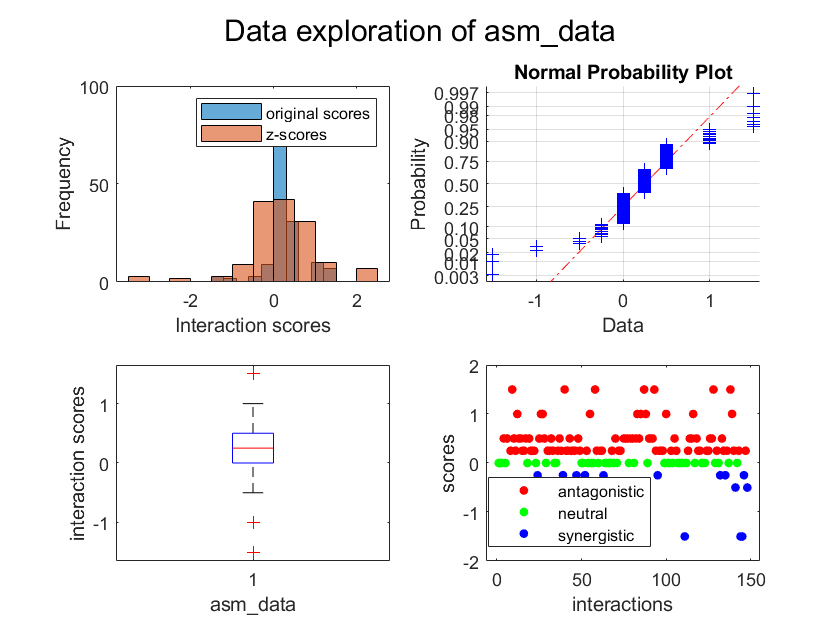

[summary,drugList] = dataExplore(testFile);

files = dataFiles();
compareFiles = [testFile;files.natureData(1:2)];
sharedInteractions = dataCompare(compareFiles);

sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    asm_data score    ecoli_bw25113 score
    ______    ______    ______________    ___________________

    "AMK"     "NIT"            -1              -0.21472      
    "CHL"     "NIT"          0.25              0.062737      
    "DOX"     "AMK"         -0.25              -0.18107      
    "DOX"     "TOB"             0              -0.21608      
    "FUS"     "AMK"         -0.25              -0.16155      
    "FUS"     "NIT"         -0.25               0.10853      


sharedInteractionsPreview = 6×4 table
    Drug 1    Drug 2    asm_data score    ecoli_iAi1 score
    ______    ______    ______________    ________________

    "AMK"     "NIT"            -1             -0.30784    
    "CHL"     "NIT"          0.25             -0.41592    
    "DOX"     "AMK"         -0.25             -0.21358    
    "DOX"     "TOB"             0             -0.17607    
    "FUS"     "AMK"         -0.25              -0.1647    
    "FUS"     "NIT"         -0.25             -0.16241    


sharedInteractionsPreview = 8×4 table
    Drug 1    Drug 2    ecoli_bw25113 score    ecoli_iAi1 score
    ______    ______    ___________________    ________________

    "A22"     "ATM"          -0.11682              -0.23949    
    "A22"     "BLM"          -0.18842              -0.22326    
    "A22"     "MMC"          -0.15416              0.081189    
    "A22"     "PUR"           0.10034               0.10767    
    "A22"     "PYO"           0.28322             -0.082868    
    "A22"     "RIF"          0.099699               0.17919    
    "AMK"     "AZM"           0.20244              0.039346    
    "AMK"     "BZK"           0.40112              0.082268    


interactionCounts = 3×3 table
                     asm_data    ecoli_bw25113    ecoli_iAi1
                     ________    _____________    __________

    asm_data            0              6               6    
    ecoli_bw25113       0              0             316    
    ecoli_iAi1          0              0               0    


R_values = 3×3 table
                     asm_data    ecoli_bw25113    ecoli_iAi1
                     ________    _____________    __________

    asm_data            0           0.15179        -0.21251 
    ecoli_bw25113       0                 0         0.64896 
    ecoli_iAi1          0                 0               0 


P_values = 3×3 table
                     asm_data    ecoli_bw25113    ecoli_iAi1
                     ________    _____________    __________

    asm_data            0           0.81667        0.73333  
    ecoli_bw25113       0                 0              0  
    ecoli_iAi1          0                 0              0  


%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,standardize);

Run 1
Elapsed time is 18.046321 seconds.
Run 2
Elapsed time is 19.083034 seconds.
Run 3
Elapsed time is 19.162369 seconds.
Run 4
Elapsed time is 17.234658 seconds.
Run 5
Elapsed time is 26.862217 seconds.


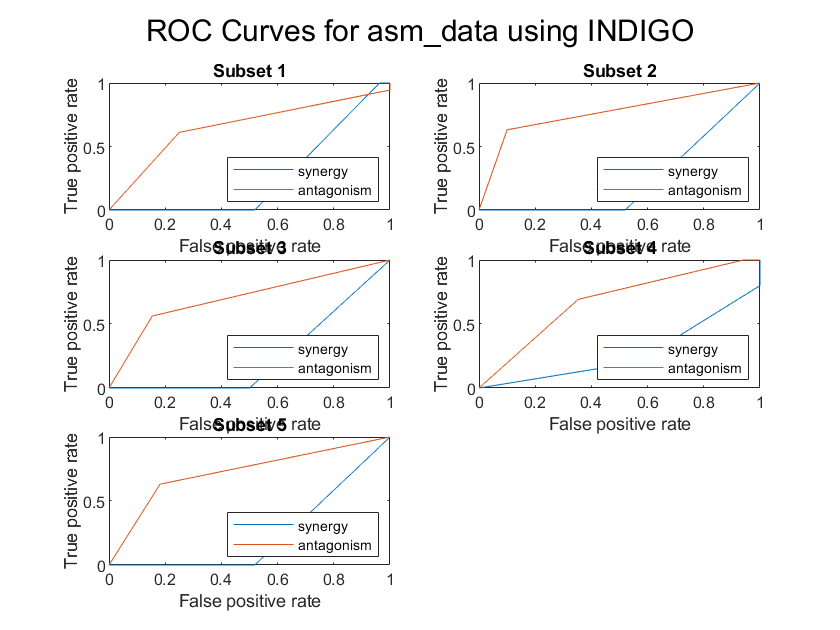

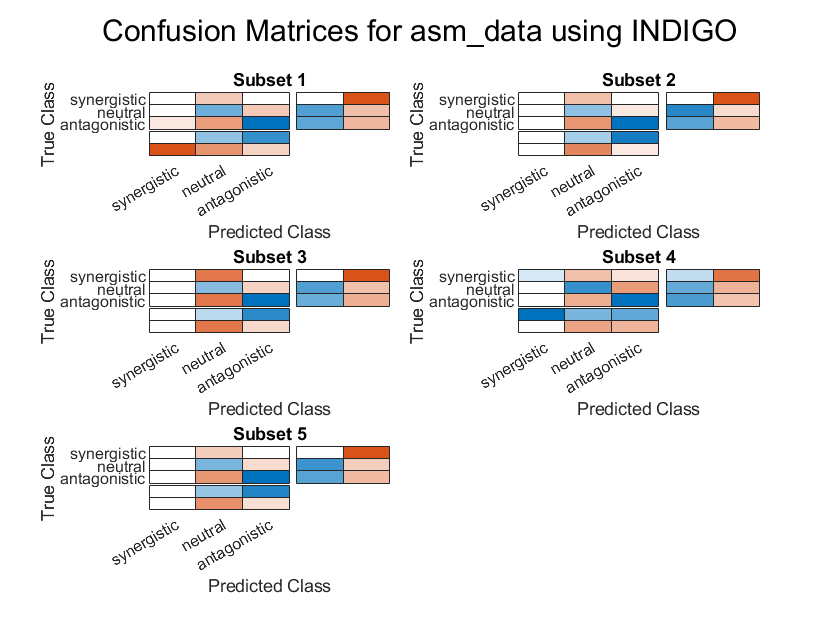

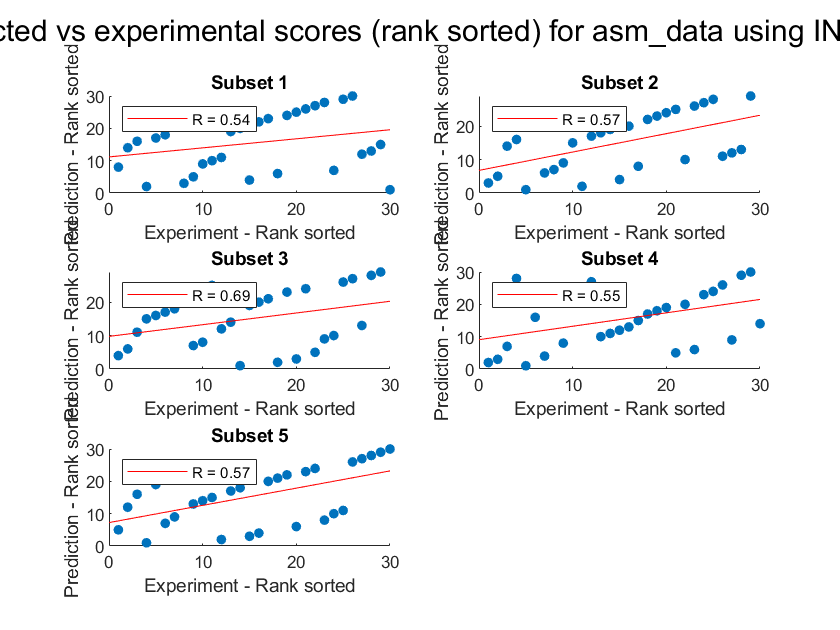

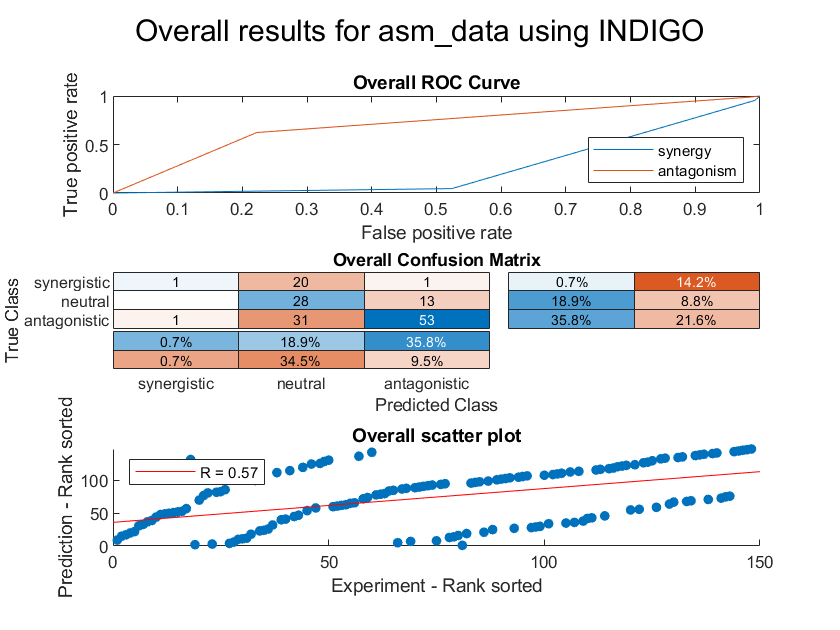

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                  Value   
                                __________

    Interactions                      29.6
    R (rank)                       0.58467
    P value                      0.0012064
    Accuracy                       0.55356
    Absolute error                 0.45977
    Precision (synergy)                NaN
    Recall (synergy)                  0.04
    Precision (antagonism)         0.79682
    Recall (antagonism)            0.62582
    Mean Guess Error              -0.43683
    Guess Accuracy (p value)    2.2592e-09
    AUC - ROC (synergy)             0.2532
    AUC - ROC (antagonism)         0.70669


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       148
    R (rank)                       0.57059
    P value                     3.7057e-14
    Accuracy                       0.55405
    Absolute error                 0.45946
    Precision (synergy)                0.5
    Recall (synergy)              0.045455
    Precision (antagonism)         0.79104
    Recall (antagonism)            0.62353
    Mean Guess Error              -0.43635
    Guess Accuracy (p value)     2.483e-42
    AUC - ROC (synergy)            0.25379
    AUC - ROC (antagonism)         0.69907


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'asm_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'nature_ecoli';
standardize = 'standardized';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 38.463431 seconds.
Run 2
Elapsed time is 17.104567 seconds.
Run 3
Elapsed time is 22.273202 seconds.
Run 4
Elapsed time is 28.584486 seconds.
Run 5
Elapsed time is 30.304311 seconds.


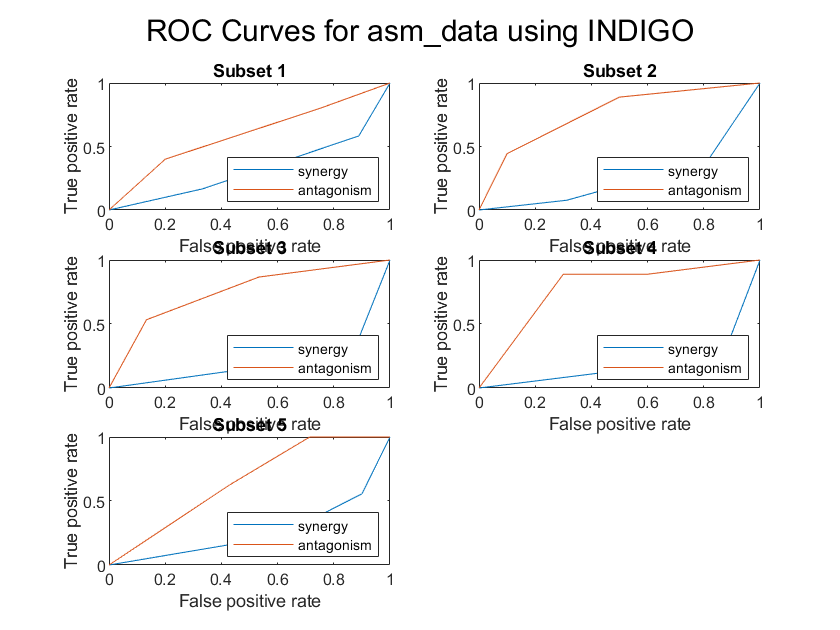

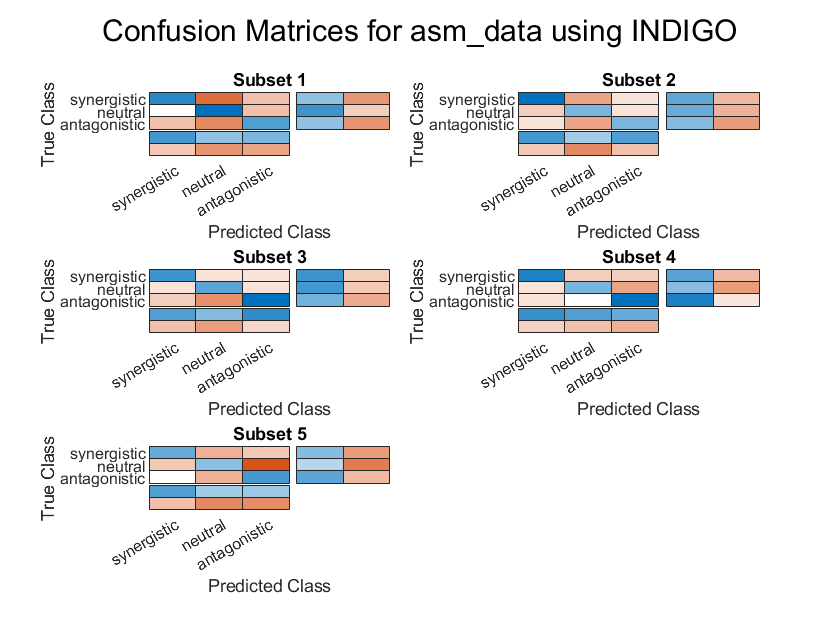

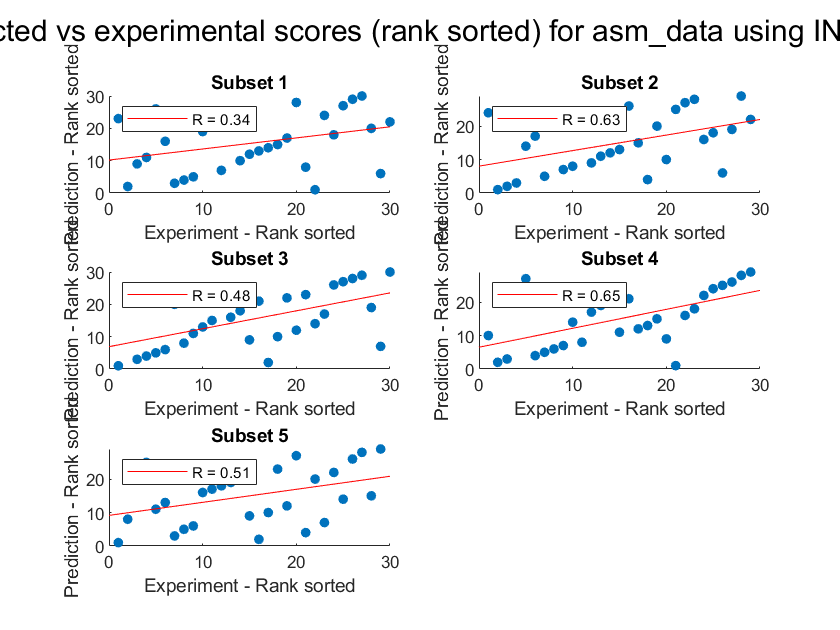

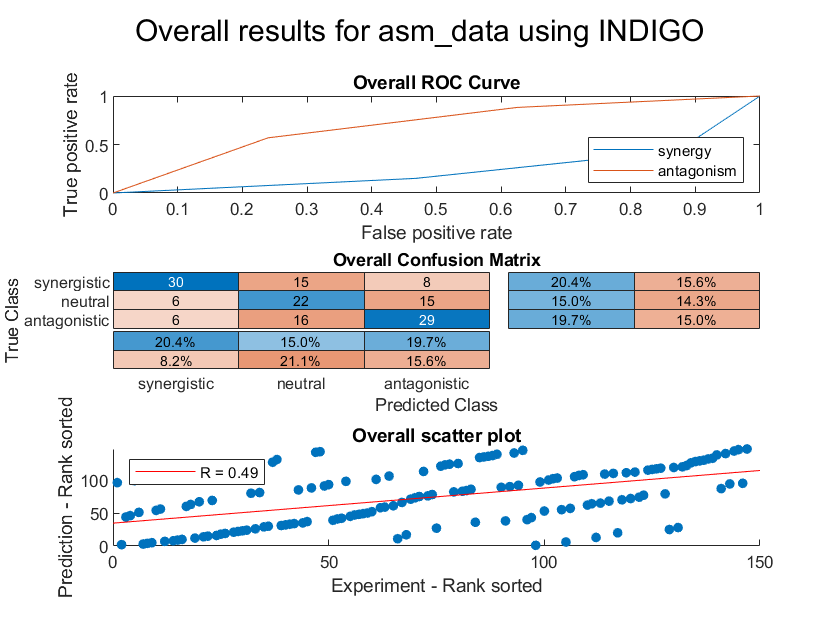

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                 Value  
                                ________

    Interactions                    29.4
    R (rank)                     0.52088
    P value                     0.015322
    Accuracy                      0.5508
    Absolute error               0.54414
    Precision (synergy)          0.71053
    Recall (synergy)             0.57257
    Precision (antagonism)       0.57905
    Recall (antagonism)          0.57833
    Mean Guess Error             -0.5508
    Guess Accuracy (p value)           0
    AUC - ROC (synergy)          0.24708
    AUC - ROC (antagonism)       0.70736


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       147
    R (rank)                       0.48533
    P value                     4.6589e-10
    Accuracy                       0.55102
    Absolute error                 0.54422
    Precision (synergy)            0.71429
    Recall (synergy)               0.56604
    Precision (antagonism)         0.55769
    Recall (antagonism)            0.56863
    Mean Guess Error              -0.55102
    Guess Accuracy (p value)             0
    AUC - ROC (synergy)            0.24508
    AUC - ROC (antagonism)         0.70067


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'asm_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_bw25113.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'',standardize);

Run 1
Elapsed time is 69.199365 seconds.
Run 2
Elapsed time is 65.876744 seconds.
Run 3
Elapsed time is 61.906408 seconds.
Run 4
Elapsed time is 51.261750 seconds.
Run 5
Elapsed time is 64.992981 seconds.


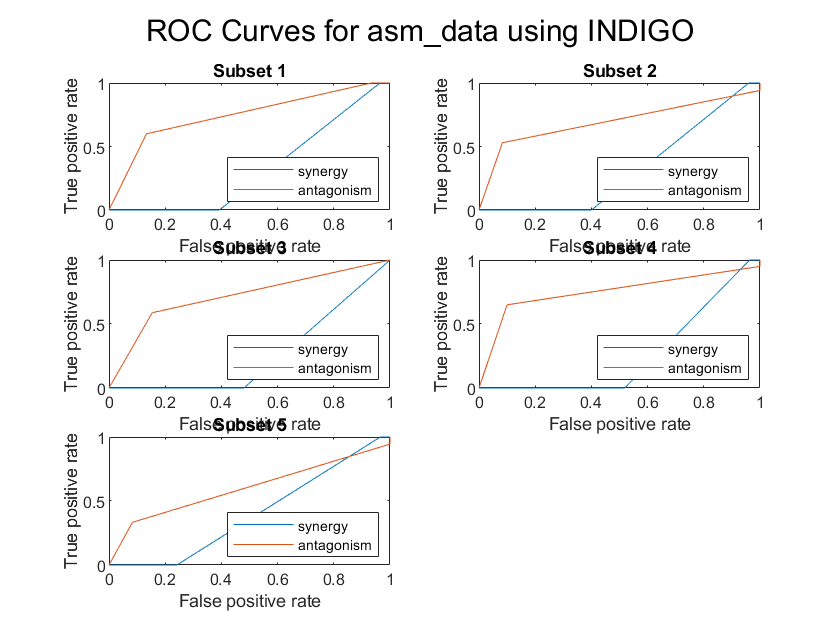

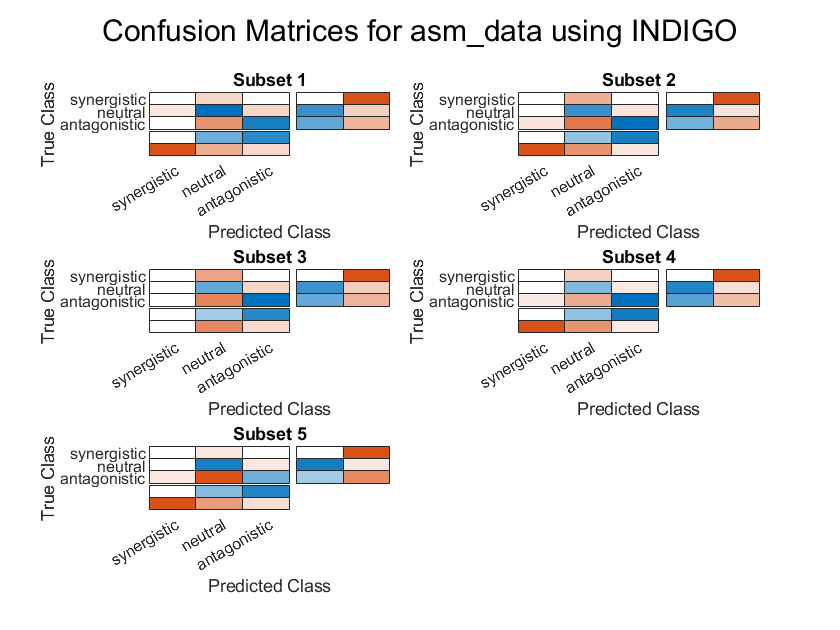

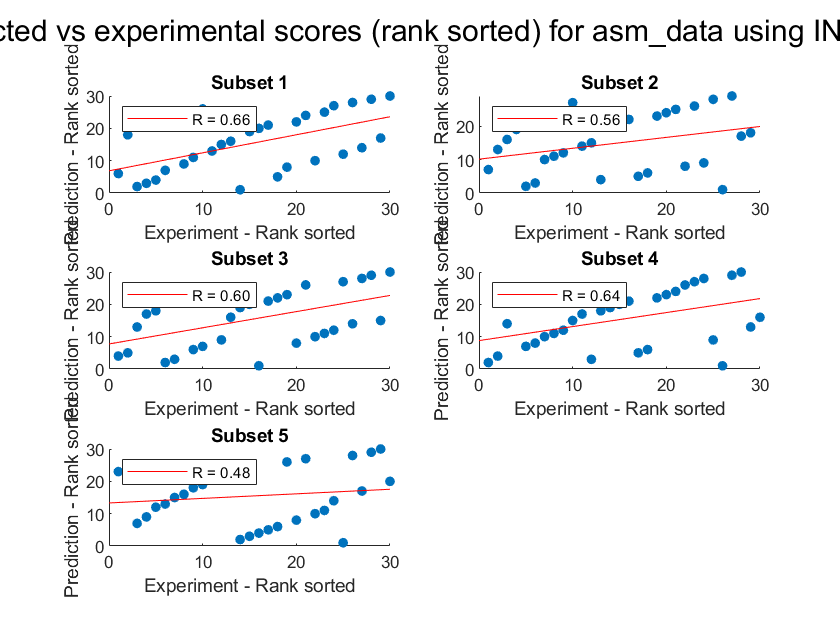

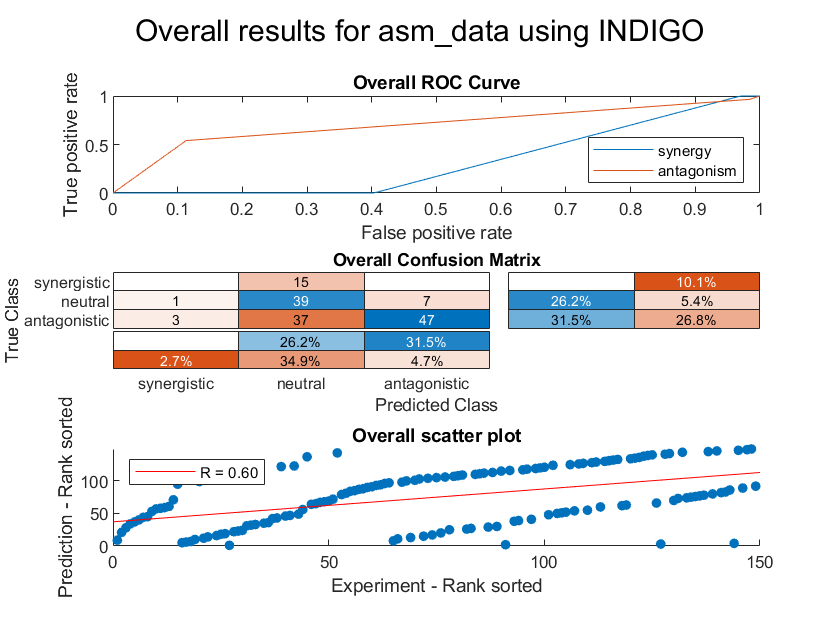

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                  Value   
                                __________

    Interactions                      29.8
    R (rank)                         0.587
    P value                      0.0019432
    Accuracy                       0.57701
    Absolute error                 0.44322
    Precision (synergy)                NaN
    Recall (synergy)                     0
    Precision (antagonism)         0.86745
    Recall (antagonism)             0.5402
    Mean Guess Error              -0.44514
    Guess Accuracy (p value)    6.3724e-11
    AUC - ROC (synergy)            0.31145
    AUC - ROC (antagonism)          0.7024


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       149
    R (rank)                       0.60486
    P value                     3.1011e-16
    Accuracy                       0.57718
    Absolute error                 0.44295
    Precision (synergy)                  0
    Recall (synergy)                     0
    Precision (antagonism)         0.87037
    Recall (antagonism)            0.54023
    Mean Guess Error              -0.44557
    Guess Accuracy (p value)    6.4414e-40
    AUC - ROC (synergy)            0.31343
    AUC - ROC (antagonism)         0.70208


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))

%make sure you are starting in folder one step above code, data and results
%folders
testFile = 'asm_data.xlsx';
valMethod = 'cv';
K = 5;
orthology = '';
trainingData = 'ecoli_iAi1.xlsx';
standardize = '';

%run indigo on data
indigoSummary = indigoRun(testFile,valMethod,K,orthology,trainingData,'ecoli_iAi1_orthologs.xlsx',standardize);

Run 1
Elapsed time is 56.192585 seconds.
Run 2
Elapsed time is 59.007944 seconds.
Run 3
Elapsed time is 58.029122 seconds.
Run 4
Elapsed time is 60.114854 seconds.
Run 5
Elapsed time is 56.043377 seconds.


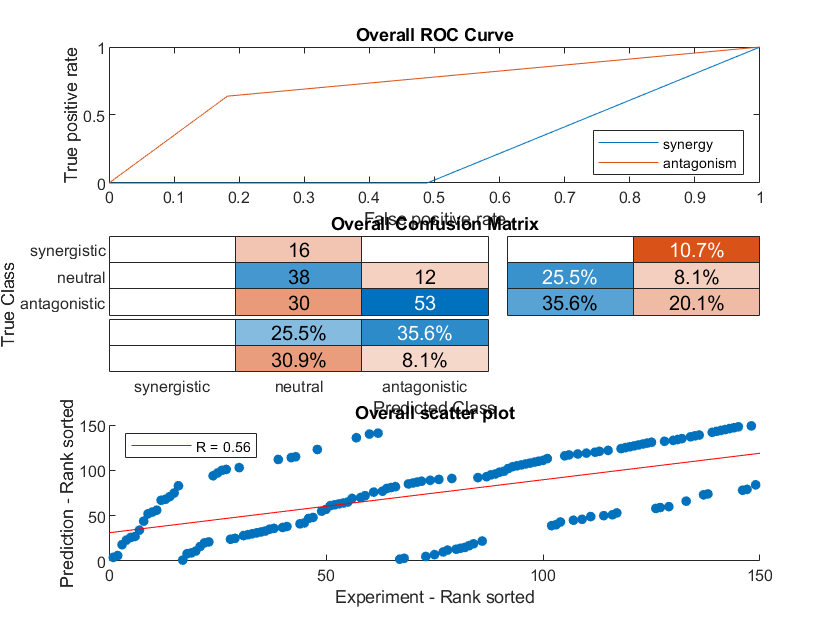

resultsTable = 5×13 table
                Interactions    R (rank)     P value      Accuracy    Absolute error    Precision (synergy)    Recall (synergy)    Precision (antagonism)    Recall (antagonism)    Mean Guess Error    Guess Accuracy (p value)    AUC - ROC (synergy)    AUC - ROC (antagonism)
                ____________    ________    __________    ________    ______________    ___________________    ________________    ______________________    ___________________    ________________    ________________________    ___________________    ________________

averagesTable = 13×1 table
                                  Value   
                                __________

    Interactions                      29.8
    R (rank)                       0.59656
    P value                      0.0037039
    Accuracy                       0.61103
    Absolute error                 0.38897
    Precision (synergy)                NaN
    Recall (synergy)                     0
    Precision (antagonism)         0.83678
    Recall (antagonism)            0.66979
    Mean Guess Error               -0.4812
    Guess Accuracy (p value)    2.0606e-11
    AUC - ROC (synergy)            0.25471
    AUC - ROC (antagonism)         0.75235


overviewTable = 13×1 table
                                  Value   
                                __________

    Interactions                       149
    R (rank)                        0.5611
    P value                       9.85e-14
    Accuracy                       0.61074
    Absolute error                 0.38926
    Precision (synergy)                NaN
    Recall (synergy)                     0
    Precision (antagonism)         0.81538
    Recall (antagonism)            0.63855
    Mean Guess Error              -0.46517
    Guess Accuracy (p value)    2.5826e-39
    AUC - ROC (synergy)            0.25564
    AUC - ROC (antagonism)         0.72837


%analysis
[stats,averages,overview] = analyze(indigoSummary);

%save results
save(saveIndigo(indigoSummary))